Sprawozdanie 4 (charakterystyki czasowe i częstotliwościowe)

1. Regulator PI

Wyznaczanie odpowiedzi skokowych:

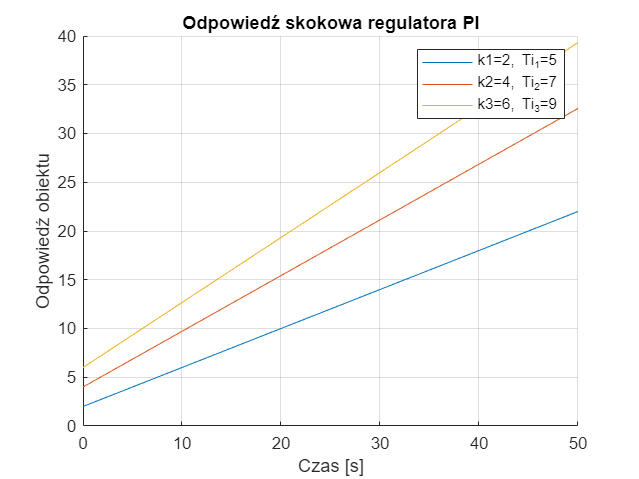

k1 = 2;
k2 = 4;
k3 = 6;
Ti_1 = 5;
Ti_2 = 7;
Ti_3 = 9;
t = linspace(0, 50);


licz1 = [k1*Ti_1, k1];
mian1 = [Ti_1, 0];

licz2 = [k2*Ti_2, k2];
mian2 = [Ti_2, 0];

licz3 = [k3*Ti_3, k3];
mian3 = [Ti_3, 0];

figure
hold on
[y1, ~, t1] = step(licz1, mian1, t);
[y2, ~, t2] = step(licz2, mian2, t);
[y3, ~, t3] = step(licz3, mian3, t);
plot(t1, y1, t2, y2, t3, y3)
title('Odpowiedź skokowa regulatora PI')
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9')
xlabel("Czas [s]")
ylabel("Odpowiedź obiektu")
grid on
hold off

Wyznaczanie charakterystyki amplitudowo fazowej:

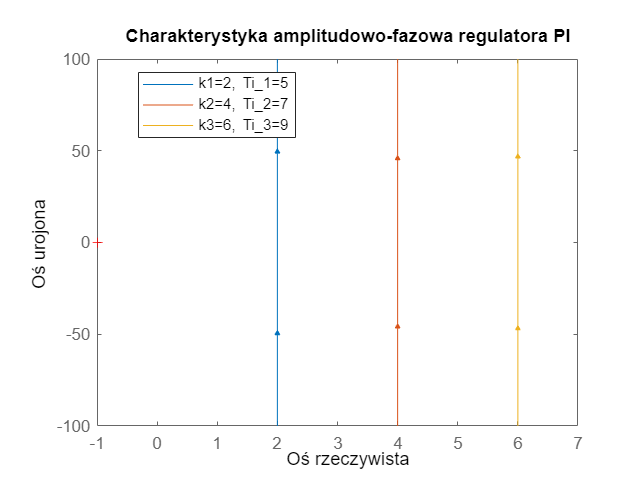

k1 = 2;
k2 = 4;
k3 = 6;
Ti_1 = 5;
Ti_2 = 7;
Ti_3 = 9;
t = linspace(0, 50);

licz1 = [k1*Ti_1, k1];
mian1 = [Ti_1, 0];

licz2 = [k2*Ti_2, k2];
mian2 = [Ti_2, 0];

licz3 = [k3*Ti_3, k3];
mian3 = [Ti_3, 0];

figure
hold on
nyquist(licz1,mian1) 
nyquist(licz2,mian2) 
nyquist(licz3,mian3)
title("Charakterystyka amplitudowo-fazowa regulatora PI")
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9', location = "best")
xlabel("Oś rzeczywista")
ylabel("Oś urojona")
hold off

Moduł i faza w skali logarytmicznej:

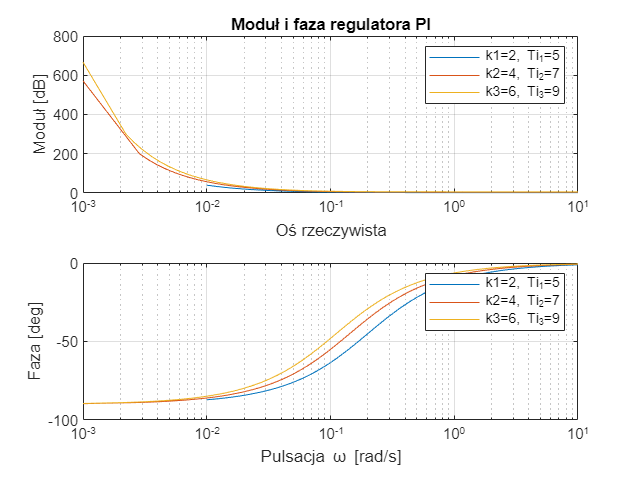

k1 = 2;
k2 = 4;
k3 = 6;
Ti_1 = 5;
Ti_2 = 7;
Ti_3 = 9;
t = linspace(0, 50);

licz1 = [k1*Ti_1, k1];
mian1 = [Ti_1, 0];

licz2 = [k2*Ti_2, k2];
mian2 = [Ti_2, 0];

licz3 = [k3*Ti_3, k3];
mian3 = [Ti_3, 0];

[mag1, ph1, w1] = fbode(licz1, mian1);
[mag2, ph2, w2] = fbode(licz2, mian2);
[mag3, ph3, w3] = fbode(licz3, mian3);

figure
subplot(2,1,1)
semilogx(w1, mag1, w2, mag2, w3, mag3)
title("Moduł i faza regulatora PI")
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9')
xlabel("Oś rzeczywista")
ylabel("Moduł [dB]")
grid on


subplot(2,1,2)
semilogx(w1, ph1, w2, ph2, w3, ph3)
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9')
xlabel("Pulsacja \omega [rad/s]")
ylabel("Faza [deg]")
grid on

2. Regulator PD

Wyznaczanie odpowiedzi skokowych:

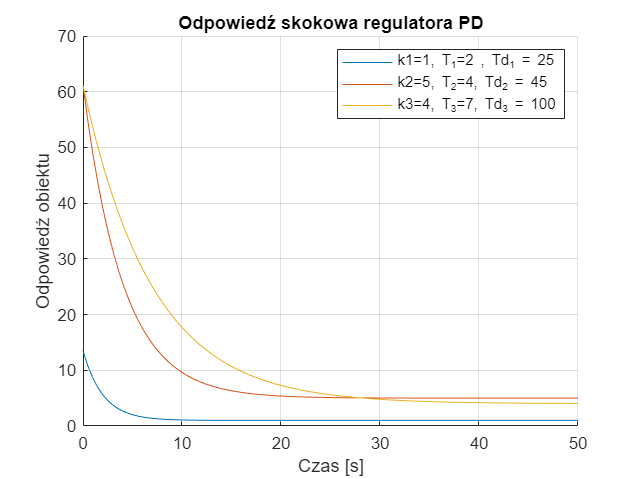

k1 = 1;
k2 = 5;
k3 = 4;
T_1 = 2;
T_2 = 4;
T_3 = 7;
Td_1 = 25;
Td_2 = 45;
Td_3 = 100;
t = linspace(0, 50);


licz1 = [k1*(T_1 +Td_1), k1];
mian1 = [T_1, 1];

licz2 = [k2*(T_2 +Td_2), k2];
mian2 = [T_2, 1];

licz3 = [k3*(T_3 +Td_3), k3];
mian3 = [T_3, 1];

figure
hold on
[y1, ~, t1] = step(licz1, mian1, t);
[y2, ~, t2] = step(licz2, mian2, t);
[y3, ~, t3] = step(licz3, mian3, t);
plot(t1, y1, t2, y2, t3, y3)
title('Odpowiedź skokowa regulatora PD')
legend('k1=1, T_1=2 , Td_1 = 25', 'k2=5, T_2=4, Td_2 = 45', 'k3=4, T_3=7, Td_3 = 100')
xlabel("Czas [s]")
ylabel("Odpowiedź obiektu")
grid on
hold off

Wyznaczanie charakterystyki amplitudowo fazowej:

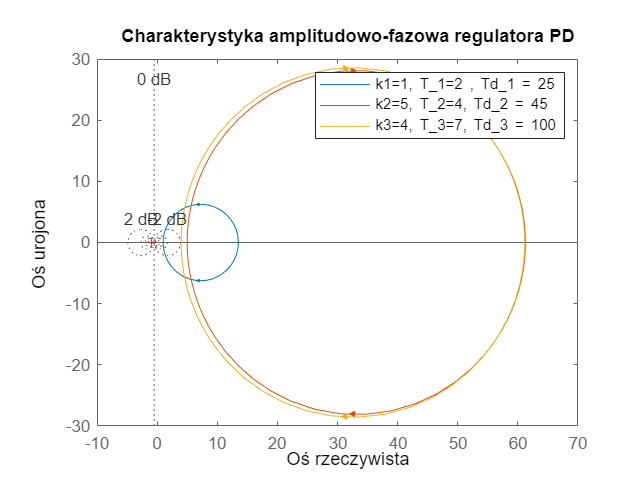

k1 = 1;
k2 = 5;
k3 = 4;
T_1 = 2;
T_2 = 4;
T_3 = 7;
Td_1 = 25;
Td_2 = 45;
Td_3 = 100;
t = linspace(0, 50);


licz1 = [k1*(T_1 +Td_1), k1];
mian1 = [T_1, 1];

licz2 = [k2*(T_2 +Td_2), k2];
mian2 = [T_2, 1];

licz3 = [k3*(T_3 +Td_3), k3];
mian3 = [T_3, 1];

figure
hold on
nyquist(licz1,mian1) 
nyquist(licz2,mian2) 
nyquist(licz3,mian3)
title("Charakterystyka amplitudowo-fazowa regulatora PD")
legend('k1=1, T_1=2 , Td_1 = 25', 'k2=5, T_2=4, Td_2 = 45', 'k3=4, T_3=7, Td_3 = 100')
xlabel("Oś rzeczywista")
ylabel("Oś urojona")
grid on
hold off

Moduł i faza w skali logarytmicznej:

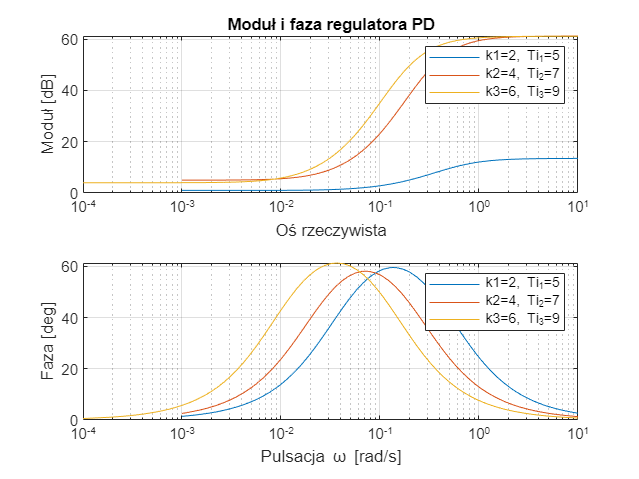

k1 = 1;
k2 = 5;
k3 = 4;
T_1 = 2;
T_2 = 4;
T_3 = 7;
Td_1 = 25;
Td_2 = 45;
Td_3 = 100;
t = linspace(0, 50);


licz1 = [k1*(T_1 +Td_1), k1];
mian1 = [T_1, 1];

licz2 = [k2*(T_2 +Td_2), k2];
mian2 = [T_2, 1];

licz3 = [k3*(T_3 +Td_3), k3];
mian3 = [T_3, 1];

[mag1, ph1, w1] = fbode(licz1, mian1);
[mag2, ph2, w2] = fbode(licz2, mian2);
[mag3, ph3, w3] = fbode(licz3, mian3);

figure
subplot(2,1,1)
semilogx(w1, mag1, w2, mag2, w3, mag3)
title("Moduł i faza regulatora PD")
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9')
xlabel("Oś rzeczywista")
ylabel("Moduł [dB]")
grid on


subplot(2,1,2)
semilogx(w1, ph1, w2, ph2, w3, ph3)
legend('k1=2, Ti_1=5', 'k2=4, Ti_2=7', 'k3=6, Ti_3=9')
xlabel("Pulsacja \omega [rad/s]")
ylabel("Faza [deg]")
grid on

3. Regulator PID

Wyznaczanie charakterystyki skokowej:

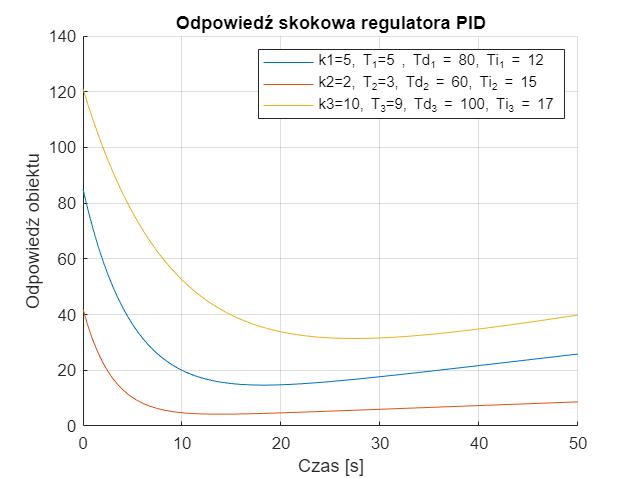

k1 = 5;
k2 = 2;
k3 = 10;
T_1 = 5;
T_2 = 3;
T_3 = 9;
Td_1 = 80;
Td_2 = 60;
Td_3 = 100;
Ti_1 = 12;
Ti_2 = 15;
Ti_3 = 17;
t = linspace(0, 50);

licz1 = [k1*Ti_1*(T_1+Td_1), k1*(T_1+Ti_1), k1];
mian1 = [Ti_1*T_1, Ti_1, 0];

licz2 = [k2*Ti_2*(T_2+Td_2), k2*(T_2+Ti_2), k2];
mian2 = [Ti_2*T_2, Ti_2, 0];

licz3 = [k3*Ti_3*(T_3+Td_3), k3*(T_3+Ti_3), k3];
mian3 = [Ti_3*T_3, Ti_3, 0];

figure
hold on
[y1, ~, t1] = step(licz1, mian1, t);
[y2, ~, t2] = step(licz2, mian2, t);
[y3, ~, t3] = step(licz3, mian3, t);
plot(t1, y1, t2, y2, t3, y3)
title('Odpowiedź skokowa regulatora PID')
legend('k1=5, T_1=5 , Td_1 = 80, Ti_1 = 12', 'k2=2, T_2=3, Td_2 = 60, Ti_2 = 15', 'k3=10, T_3=9, Td_3 = 100, Ti_3 = 17')
xlabel("Czas [s]")
ylabel("Odpowiedź obiektu")
grid on
hold off

Wyznaczanie charakterystyki amplitudowo fazowej:

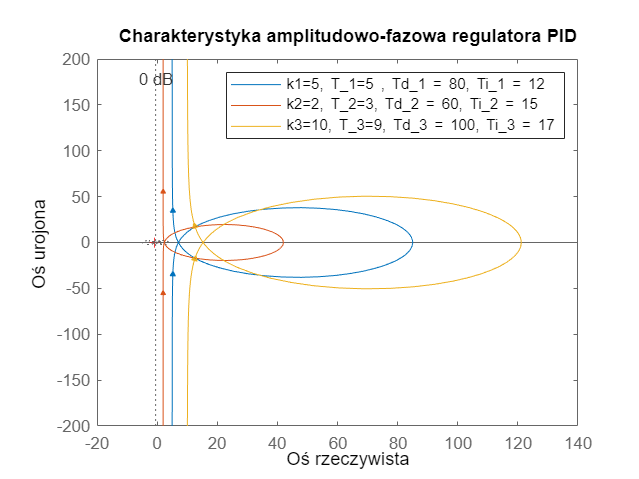

k1 = 5;
k2 = 2;
k3 = 10;
T_1 = 5;
T_2 = 3;
T_3 = 9;
Td_1 = 80;
Td_2 = 60;
Td_3 = 100;
Ti_1 = 12;
Ti_2 = 15;
Ti_3 = 17;
t = linspace(0, 50);

licz1 = [k1*Ti_1*(T_1+Td_1), k1*(T_1+Ti_1), k1];
mian1 = [Ti_1*T_1, Ti_1, 0];

licz2 = [k2*Ti_2*(T_2+Td_2), k2*(T_2+Ti_2), k2];
mian2 = [Ti_2*T_2, Ti_2, 0];

licz3 = [k3*Ti_3*(T_3+Td_3), k3*(T_3+Ti_3), k3];
mian3 = [Ti_3*T_3, Ti_3, 0];

figure
hold on
nyquist(licz1,mian1) 
nyquist(licz2,mian2) 
nyquist(licz3,mian3)
title("Charakterystyka amplitudowo-fazowa regulatora PID")
legend('k1=5, T_1=5 , Td_1 = 80, Ti_1 = 12', 'k2=2, T_2=3, Td_2 = 60, Ti_2 = 15', 'k3=10, T_3=9, Td_3 = 100, Ti_3 = 17')
xlabel("Oś rzeczywista")
ylabel("Oś urojona")
grid on
hold off

Moduł i faza w skali logarytmicznej:

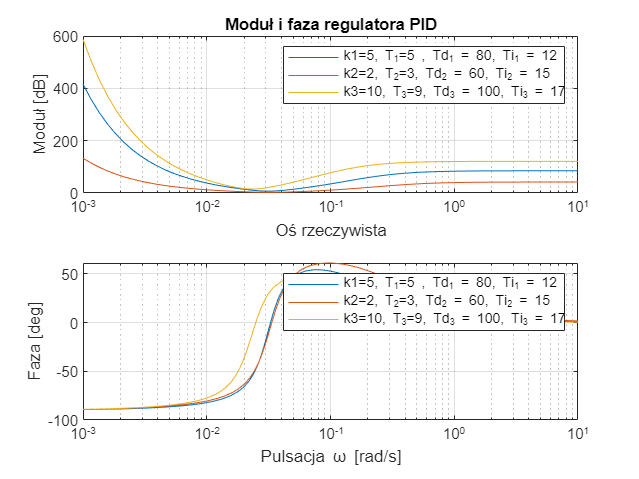

k1 = 5;
k2 = 2;
k3 = 10;
T_1 = 5;
T_2 = 3;
T_3 = 9;
Td_1 = 80;
Td_2 = 60;
Td_3 = 100;
Ti_1 = 12;
Ti_2 = 15;
Ti_3 = 17;
t = linspace(0, 50);

licz1 = [k1*Ti_1*(T_1+Td_1), k1*(T_1+Ti_1), k1];
mian1 = [Ti_1*T_1, Ti_1, 0];

licz2 = [k2*Ti_2*(T_2+Td_2), k2*(T_2+Ti_2), k2];
mian2 = [Ti_2*T_2, Ti_2, 0];

licz3 = [k3*Ti_3*(T_3+Td_3), k3*(T_3+Ti_3), k3];
mian3 = [Ti_3*T_3, Ti_3, 0];

[mag1, ph1, w1] = fbode(licz1, mian1);
[mag2, ph2, w2] = fbode(licz2, mian2);
[mag3, ph3, w3] = fbode(licz3, mian3);

figure
subplot(2,1,1)
semilogx(w1, mag1, w2, mag2, w3, mag3)
title("Moduł i faza regulatora PID")
legend('k1=5, T_1=5 , Td_1 = 80, Ti_1 = 12', 'k2=2, T_2=3, Td_2 = 60, Ti_2 = 15', 'k3=10, T_3=9, Td_3 = 100, Ti_3 = 17')
xlabel("Oś rzeczywista")
ylabel("Moduł [dB]")
grid on


subplot(2,1,2)
semilogx(w1, ph1, w2, ph2, w3, ph3)
legend('k1=5, T_1=5 , Td_1 = 80, Ti_1 = 12', 'k2=2, T_2=3, Td_2 = 60, Ti_2 = 15', 'k3=10, T_3=9, Td_3 = 100, Ti_3 = 17')
xlabel("Pulsacja \omega [rad/s]")
ylabel("Faza [deg]")
grid on